clc
data=load('infla.txt')

data =         3741
        3608
        3735
        3695
        3810
        3819
        3291
        3053
        3908
        4035


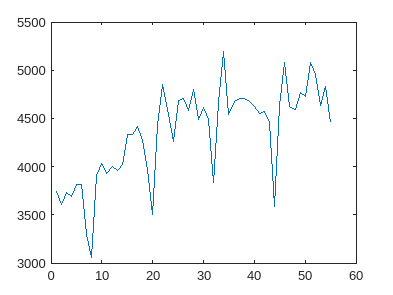

% Create a plot of the data
plot(data);

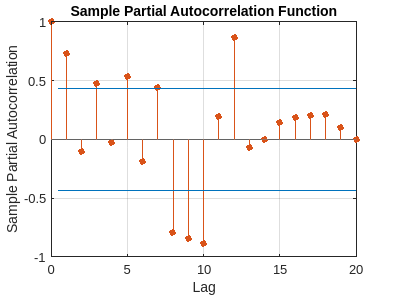

auto_correlation=autocorr(data);
parcorr(auto_correlation)

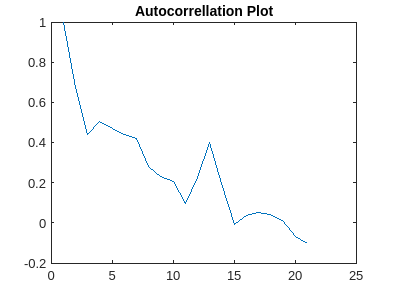

plot(auto_correlation)
title('Autocorrellation Plot');

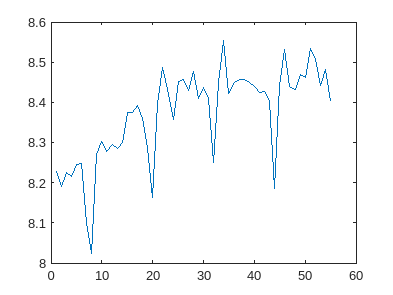

stable=log(data);
plot(stable);

%first differenciation
D1=LagOp({1,-1},'Lags',[0,1]);
dY=filter(D1,data);
%second differenciation
% D2=D1*D1;
% dY=filter(D2,data);
%enlever la saisonnalite
D2=LagOp({1,-1},'Lags',[0,12]);
ddY=filter(D2,data)

ddY =    220
   417
   601
   640
   602
   449
   677
   452
   526
   819


%pour enlever la saisonnalite et la tendance
D11= LagOp({1,-1},'Lags',[0,1])

D11 =     1-D Lag Operator Polynomial:
    -----------------------------
        Coefficients: [1 -1]
                Lags: [0 1]
              Degree: 1
           Dimension: 1

D112= LagOp({1,-1},'Lags',[0,12])

D112 =     1-D Lag Operator Polynomial:
    -----------------------------
        Coefficients: [1 -1]
                Lags: [0 12]
              Degree: 12
           Dimension: 1

D12= D11*D112;
dddY=filter(D12,data)

dddY =    197
   184
    39
   -38
  -153
   228
  -225
    74
   293
  -160


model1=arima(1,1,1)

model1 =   arima with properties:

     Description: "ARIMA(1,1,1) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 2
               D: 1
               Q: 1
        Constant: NaN
              AR: {NaN} at lag [1]
             SAR: {}
              MA: {NaN} at lag [1]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: NaN

model2=arima(2,1,1)

model2 =   arima with properties:

     Description: "ARIMA(2,1,1) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 3
               D: 1
               Q: 1
        Constant: NaN
              AR: {NaN NaN} at lags [1 2]
             SAR: {}
              MA: {NaN} at lag [1]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: NaN

model3=arima('Constant',0,'ARLags',1:2,'MALags',1);

%estimation
fit1=estimate(model1,data);

 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant     13.387        2.8932          4.627      3.7105e-06
    AR{1}       0.34904       0.14309         2.4394        0.014712
    MA{1}            -1      0.056459        -17.712      3.3959e-70
    Variance      96093         17503         5.4902       4.014e-08



fit2=estimate(model2,data);

 
    ARIMA(2,1,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant      18.939        11.696         1.6193         0.10539
    AR{1}        0.26609       0.17578         1.5138         0.13009
    AR{2}       -0.32876       0.18061        -1.8202        0.068723
    MA{1}       -0.77846       0.13144        -5.9226      3.1681e-09
    Variance       93806         17219         5.4478      5.0996e-08



fit3=estimate(model3,data);

 
    ARIMA(2,0,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0             0            NaN             NaN
    AR{1}           1.2829       0.17302         7.4146      1.2198e-13
    AR{2}         -0.28291       0.17203        -1.6445         0.10007
    MA{1}         -0.80963       0.14189        -5.7059      1.1572e-08
    Variance    1.0866e+05         19324         5.6228      1.8786e-08



%erreur
e1=infer(fit1,data);
e2=infer(fit2,data);
e3=infer(fit3,data);
[Yf,YMSE]=forecast(fit1,4,'Y0',data);
upper=Yf+1.96*sqrt(YMSE)

upper = 1.0e+03 *

    5.3762
    5.5332
    5.5931
    5.6264


lower=Yf-1.96*sqrt(YMSE)

lower = 1.0e+03 *

    4.1610
    4.2462
    4.2976
    4.3299


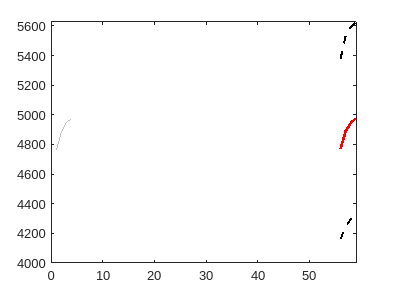

N=length(data);

figure(9)
plot(Yf,'color',[.75,.75,.75]);
hold on
h1=plot(N+1:N+4,Yf,'r','LineWidth',2);
h2=plot(N+1:N+4,upper,'k--','LineWidth',1.5);
plot(N+1:N+4,lower,"k--",'LineWidth',1.5);
xlim([0,N+4])
hold off

% calcul MAPE
%model1
MAPE1=(100/N)*sum(abs( e1./data))

MAPE1 = 5.3231

%model2
MAPE2=(100/N)*sum(abs( e2./data))

MAPE2 = 5.5947

%model3
MAPE3=(100/N)*sum(abs( e3./data))

MAPE3 = 5.8602

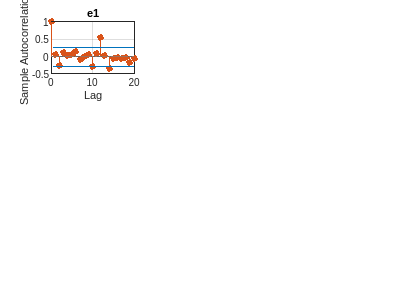


figure
subplot(3,3,1)
autocorr(e1)
title('e1')

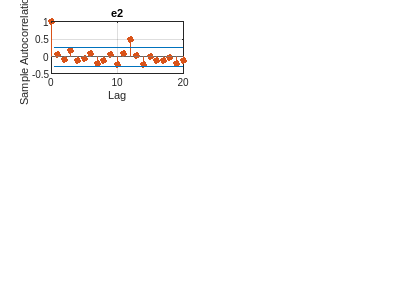


zsubplot(3,2,1)
autocorr(e2)
title('e2')

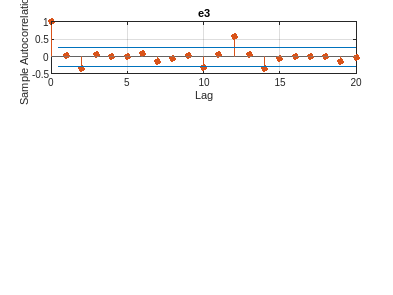


subplot(3,1,1)
autocorr(e3)
title('e3')